ECE 537 

Exercise #4

Group 5

Muqian Gui ----- V00870654

Hang Ruan ----- V00923058

% Q1
clc;
clear all;
close all;

load("Exercise_4_Data.mat");

Q2

For a dataset with 100 dimensions, Totally 1000 samples might not good enough to represent a dense sampling. As the dimensionality increases, the volume of the space grows exponentially. 100^100 sampling required to fuly represent the dataset.

If both classes are Gaussian distributed and the covariance matrices are not too large. It is possibile to conclude that the dataset represents a dense sampling. But if the means of the distributions are closer together or a large covariance matrices exit. The dataset can be regarded as well represented.

% Q3
% Training set & Testing set obtained based on the randmoly select index array from the Exercise_4_Data
train_data = a(Train_indx,:);
test_data = a(Test_indx,:);
y_train = classes(:,Train_indx);
y_train_trans = y_train';
y_test = classes(:,Test_indx);

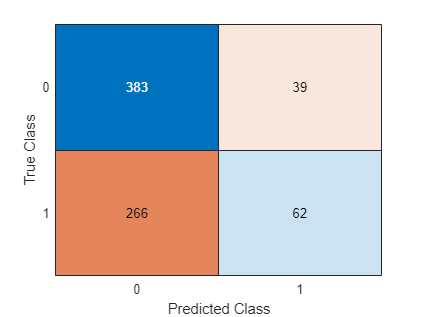

cm_PCA =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


% Q4 & Q5
% PCA transfromed training dataset & generate Bayes decision boundaries
train_data_PCA = PCA(train_data,3);
test_data_PCA = PCA(test_data,3);

mdl = fitcnb(train_data_PCA,y_train );
pre = predict (mdl,test_data_PCA);
cm_PCA = confusionchart(y_test, pre)

Q6

According to hte obtained confusion matrix, it can be concluded that PCA is  not a correct approach to apply for addressing classification in this case. PCA is primarily used for dimensionality reduction with the most significant variance and capture the linear relationship between variables. In this case, the features with maximum variance doesn't allign with the goal of classification. Therefor, PCA doesn't perform well for classification in this dataset. 

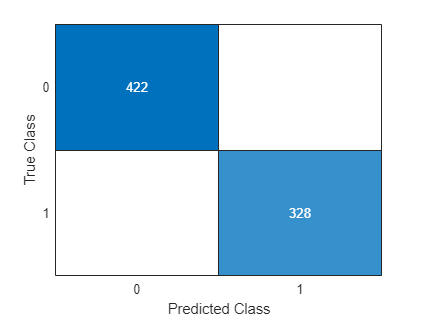

% Q7 & Q8

% find mean and std of each measurement
mean_meas = mean(train_data);
std_meas = std(train_data);

matrix_train = (train_data - mean_meas)./std_meas;
matrix_eval = (test_data - mean_meas)./std_meas;


% find the index for each class
matrix_train_0_idx = find(y_train_trans == 0);
matrix_train_1_idx = find(y_train_trans == 1);  

% pull out data for each class from the data set
matrix_train_0 = matrix_train(matrix_train_0_idx,:);
matrix_train_1 = matrix_train(matrix_train_1_idx,:);
N_0 = height(matrix_train_0);
N_1 = height(matrix_train_1);


% Perform FLD on the dataset
mu_train_0 = mean(matrix_train_1,1);
mu_train_1 = mean(matrix_train_0,1);
mu_train = mean(matrix_train,1);
mu_test = mean(matrix_eval);


% within class scatter matrix
Sw =  N_0 * cov(matrix_train_0) + N_1 * cov(matrix_train_1);

Sb = N_0 * ((mu_train_0)' * (mu_train_0 - mu_train))...
   + N_1 * ((mu_train_1)' * (mu_train_1 - mu_train));

[V,D] = eig(Sb,Sw);
eig_value = diag(D);
[sort_value, sort_idx] = sort(eig_value, 'descend');
W = V(:,sort_idx(1:1));

transform_train_FLD = (matrix_train-mu_train) * W;
transform_test_FLD = (matrix_eval-mu_test) * W;

mdl = fitcnb(transform_train_FLD,y_train );
pre = predict (mdl,transform_test_FLD);
cm_FLD = confusionchart(y_test, pre);


% Applying FLD on our data before using Bayes classification achieved
% outstanding results and it learned the best linear decision boundary for
% our dataset

Q9

According to the results obtained here, FLD did perfect on classification in this case. FLD considers the class labels during transformation and focus on maximizing the separability between classes. In this case, the feature obtained from FLD is more informative for classification than the original features. It shows strong linear relationship between FLD feature and class labels. Compare with PCA transform, FLD capture the linear relationship between the features and the label. In addition, FLD also assume the dataset is Gaussian distributions, therefor, the perfect results obtained from FLD also indicates the dataset is Gaussian distribution. 

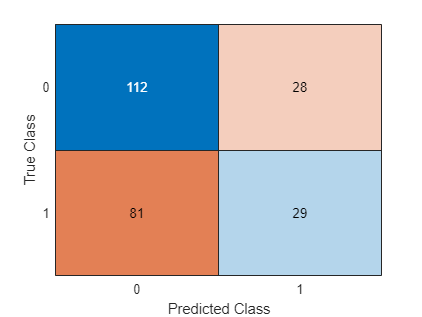

cm_10 =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


% Q10

mdl_10 = fitcnb(test_data_PCA,y_test );
pre_10 = predict (mdl_10,train_data_PCA);
cm_10 = confusionchart(y_train, pre_10)

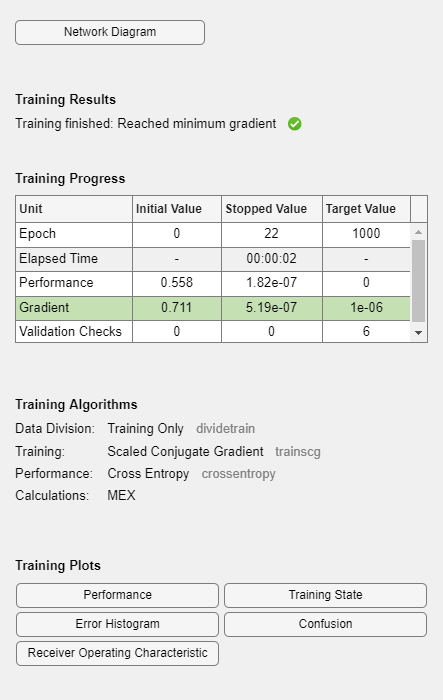

% Q11
x = train_data';
t = y_train;

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideFcn = 'dividetrain';

% Train the Network
[net,tr] = train(net,x,t);


% Test the Network
% y = net(x);
y = net(test_data');

performance = perform(net,y_test,y)

performance = 2.4777e-07

tind = round(y_test);
yind = round(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0

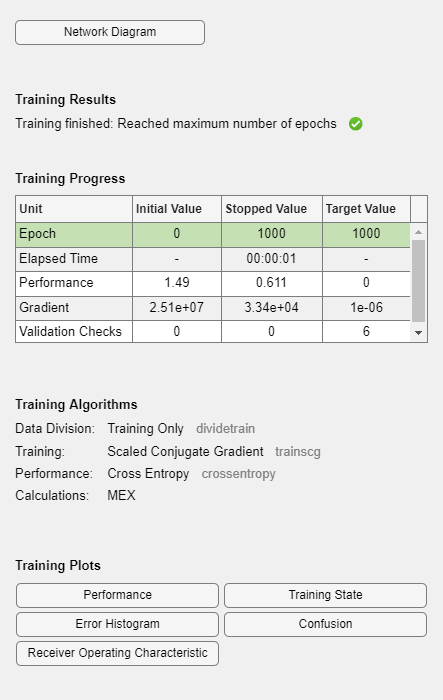

% Q12
x = train_data';
t = y_train;

trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);




%ensure that no data normalization or other preprocessing is performed
net.inputs{1}.processFcns = {};
% Setup Division of Data for Training, Validation, Testing
net.divideFcn = 'dividetrain';
% Train the Network
[net,tr] = train(net,x,t);


% Test the Network
% y = net(x);
y = net(test_data');
performance = perform(net,y_test,y)

performance = 0.6239

tind = round(y_test);
yind = round(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0.3413



% This difference in error occurs is likely due to the scale invariance
% property of our data and normalization of our data avoid any bias towards
% features with larger scales

Q 13

The neural network with normalization successfully classify data like Fisher's approach does. PCA doesn't utilize class information like Fisher's and Neural Nets do and don't perform well in this scenrio. FLD focus on gaining knowledge on the linear separability, while neural networks can capture linear and non-linear relationship. They both exhibit outstanding performance on our dataset. FLD guarantees the best linear separation between classes when the claasses are known to be linearly separable and its more efficient comparing to neural networks.

For non-linearly separable problem domains, Fisher's Linear Discriminant only capture linear decision boundaries and may not perform well. Neural Networks, on the other hand, with non-linear activation can learn non-linear relationship between features and is likely to out-perform Fisher's linear Discriminant.

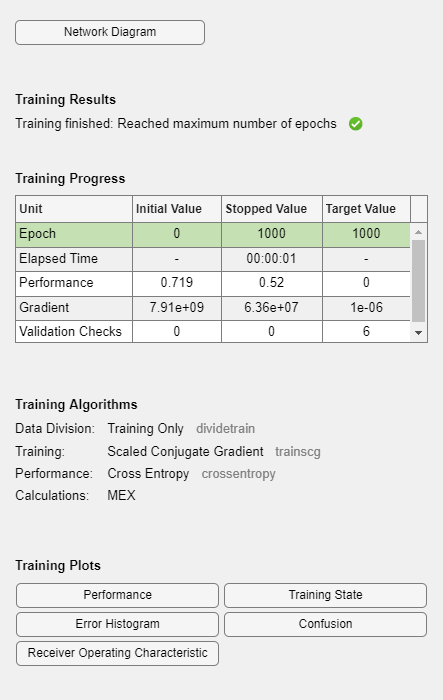

% Q 14
FLD__train_normalized = transform_train_FLD / norm(transform_train_FLD);
FLD__test_normalized = transform_test_FLD / norm(transform_test_FLD);


new_train_data = train_data - transform_train_FLD'*transform_train_FLD*train_data;
new_test_data = test_data -transform_test_FLD'*transform_test_FLD*test_data;

x = new_train_data';
t = y_train;

trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

%ensure that no data normalization or other preprocessing is performed
net.inputs{1}.processFcns = {};
% Setup Division of Data for Training, Validation, Testing
net.divideFcn = 'dividetrain';
% Train the Network
[net,tr] = train(net,x,t);


% Test the Network
% y = net(x);
y = net(new_test_data');
performance = perform(net,y_test,y)

performance = 1.6231

tind = round(y_test);
yind = round(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0.4373

If you remove the Fisher feature vector from the original data and then use this modified dataset to train a neural network for classification, it may have an impact on the performance of the classifier. Here are a few potential consequences:

Loss of discriminatory information: The Fisher feature vector is obtained through a dimensionality reduction technique that maximizes the separability between classes. By removing this feature vector, you might lose important discriminatory information that could help improve the classification accuracy.

Decreased classification performance: If the Fisher feature vector carries significant discriminatory power, removing it from the dataset might lead to a decrease in the classification performance of the neural network. The network may struggle to learn and generalize patterns effectively without this important feature.

Q 15 In my opinion, it would be common in operational data analysis settings for dense data samplings to be available a priori from which analytics systems could then be trained. For example, many real world softwares and transcation have digital logs and records behind the scene. The increasingly improvement in data storage has allowed more data to be available. 

This will provide more data for our model to learned from an yielding better performance results. Having dense data sampling also cause data abundance. Features that most contribute the most to the determination of decision boundaries needs to be identified to improve system's performance

function transformed_PCA = PCA(X,k)

mu_X = mean(X,1);
S = cov(X-mu_X);
[V,D] = eig(S);
eig_value = diag(D);
[sort_value, sort_idx] = sort (eig_value, 'descend');
E = V(:,sort_idx(1:k));
[U2, D2,V2]=svd(S);
transformed_PCA = (X -mu_X)*E;

end

 
function transformed_FLD = FLD(X,k)

end